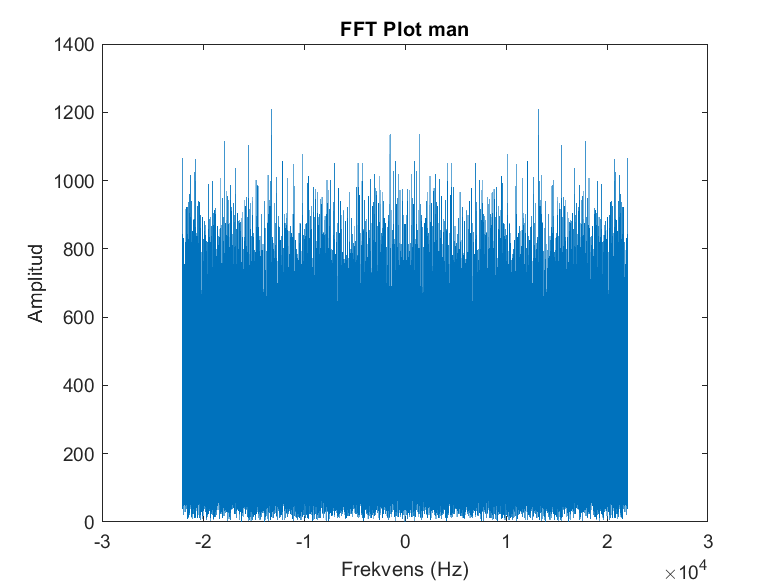

% Förberedelse 1 - Röster
fs = 44100; % Samplingsfrekvens
StopTime = 3; % seconds 
dt = 1/fs; % seconds per sample
t = 0:dt:StopTime; % seconds 
p = -10; % Effect dB (w)

f_0man = 130; % Fundamentalfrekvens för mansrröst
f_0wom = 195; % Fundamentalfrekvens för kvinnoröst

x_man = sin(2*pi*f_0man*t); % Fundamental
x_wom = sin(2*pi*f_0wom*t);

%sound(x_man, fs);
%sound(x_wom, fs);

% Förberedelse 2 - Skapa grundljudet
%F0 = sin(2*pi*f_0man*t); % Gammal F0

frekvensVektor = [1:];


whiteNoise = wgn(1,length(F0),p);

whiteNoise = whiteNoise/max(abs(whiteNoise));

%sound(whiteNoise, fs);

% FFT -------------------
fft_result = fft(whiteNoise);

N = length(whiteNoise); % Antal sampel i signalen
f = (-N/2:N/2-1) * (fs/N); 
fft_result_shifted = fftshift(fft_result);

figure;
plot(f, abs(fft_result_shifted));
xlabel('Frekvens (Hz)');
ylabel('Amplitud');
title('FFT Plot man');
% -----------------------

% Förberedelse 3 - Välj formant
% Välj formatnljud (ae, 660, 1720, 2410)
freq1 = 660;
f1Under = freq1 - freq1 * 0.1
f1Over = freq1 + freq1 * 0.1

freq2 = 1720;
f2Under = freq2 - freq2 * 0.07
f2Over = freq2 + freq2 * 0.07

freq3 = 2410;
f3Under = freq3 - freq3 * 0.05
f3Over = freq3 + freq3 * 0.05

% Normalisera brytfrekvenserna
Wn1 = ([f1Under, f1Over]/(fs/2))
Wn2 = ([f2Under, f2Over]/(fs/2))
Wn3 = ([f3Under, f3Over]/(fs/2))

% Skapa bandpassfiltren
[b1,a1] = butter(2, Wn1, 'bandpass'); % ordning 2
dataOut1 = filter(b1, a1, whiteNoise);
mag1 = db2mag(-1) * dataOut1; %formant amplitude
[b2, a2] = butter(2, Wn2, 'bandpass');
dataOut2 = filter(b2, a2, whiteNoise);
mag2 = db2mag(-12) * dataOut2;
[b3, a3] = butter(2, Wn3, 'bandpass');
dataOut3 = filter(b3, a3, whiteNoise);
mag3 = db2mag(-22) * dataOut3;

%% Lägg ihop ljuden
output = (x_man + mag1 + mag2 + mag3); %sinwave + 3 filtres of whitenoise
output = output / (max(abs(output)));

%% Skapa in-utfade vector
infadeVector = 0:5/fs:1;
outfadeVector = fliplr(infadeVector);
langd = 2*length(infadeVector);
oneVector = ones(1, length(F0)-langd);
fadeVector = [infadeVector, oneVector, outfadeVector];
output = output.*fadeVector;

% frekvensmodulerad signal
outputSine = sin(2*pi*t.*F0+(3*sin(2*pi*t.*F0*0.7+(3*sin(2*pi*t.*F0*0.5+(3*sin(2*pi*t.*F0*0.3)))))));

% Lägger till filter som förut
[b,a] = butter(2, Wn1, 'bandpass');
f1 = filter(b,a,outputSine);

[b2,a2] = butter(2, Wn2, 'bandpass');
f2 = filter(b2,a2,outputSine);

[b3,a3] = butter(2, Wn3, 'bandpass');
f3 = filter(b3,a3,outputSine);

% formant amplitud
f1mag =  db2mag(-1);
f2mag =  db2mag(-12);
f3mag =  db2mag(-22);

f1 = f1.*f1mag;
f2 = f2.*f2mag;
f3 = f3.*f3mag;

ljud = (F0+f1+f2+f3);
ljud = ljud/(max(abs(ljud)));
ljud = ljud.*fadeVector;

%% SINUS SUMMERING
counter = 0;
sinSum = 0;

while counter<29 %29 sinuswaves
    freq = f_0man*(counter+1);
    sinus = sin(2*pi*t*freq);
    sinSum = sinSum + sinus;
    counter = counter + 1;
end    

% filter
[b,a] = butter(2, Wn1, 'bandpass');
f1 = filter(b,a,sinSum);
[b2,a2] = butter(2, Wn2, 'bandpass');
f2 = filter(b2,a2,sinSum);
[b3,a3] = butter(2, Wn3, 'bandpass');
f3 = filter(b3,a3,sinSum);

% formant amplitud
f1mag =  db2mag(-1);
f2mag =  db2mag(-5);
f3mag =  db2mag(-28);

f1 = f1.*f1mag;
f2 = f2.*f2mag;
f3 = f3.*f3mag;

ljud = (F0+f1+f2+f3);
ljud = ljud/(max(abs(ljud)));
ljud = ljud.*fadeVector;

p = audioplayer(ljud, fs);
playblocking(p);